# Script to compute transfer functions from GMT pier base forces to segment tip-tilt and piston

## Preamble

clearvars;

Radians to mili arc second conversion constant

rad2mas = (180/pi * 3600 * 1000);

Root of the sum of squared values function

rss = @(x,dir)sqrt(sum(x.^2,dir));

Set telescope structural dynamics damping

sysDamp = 0.02;

## Load Integrated Model subsystems

Structural model folder

ModelFolder = '20220308_1335_MT_mount_zen_30_m1HFN_FSM_B';

Load telescope structural model

FileName = fullfile(im.lfFolder,ModelFolder,"modal_state_space_model_2ndOrder.mat");
if(~exist('outputTable','var') || true)
    
    fprintf("Loading modal model parameters from \n%s\n",FileName);
    load(FileName,'inputs2ModalF','modalDisp2Outputs',...
        'eigenfrequencies','inputTable','outputTable');
    % Handle modal paramete
    om0 = eigenfrequencies(:)*2*pi;
    proportionalDampingVec = sysDamp*ones(size(eigenfrequencies(:)));
    twice_zom = 2*proportionalDampingVec(:).*om0;
    
    % State-space model matrices
    B = [zeros(size(inputs2ModalF));inputs2ModalF];
    C = [modalDisp2Outputs,zeros(size(modalDisp2Outputs))];
    
    nm = size(inputs2ModalF,1);
    A = sparse([zeros(nm),eye(nm);-diag(om0.^2), -diag(twice_zom)]);
    
    fprintf("The model maximum eigenfrequency is %.5fHz\n",om0(end)/2/pi);
end

Loading modal model parameters from 
/Users/rromano/Workspace/gmt-data/20220308_1335_MT_mount_zen_30_m1HFN_FSM_B/modal_state_space_model_2ndOrder.mat


The model maximum eigenfrequency is 99.99385Hz


if(true)
        try
            staticSolFile = fullfile(im.lfFolder,ModelFolder,"static_reduction_model.mat");
            try
                dcg_var = 'gainMatrixMountControlled';
                load(staticSolFile,dcg_var);
                gainMatrix = gainMatrixMountControlled;
            catch
                dcg_var = 'gainMatrix';
                load(staticSolFile,dcg_var);
            end
            fprintf("Static solution gain matrix loaded successfully from variable:\n%s\n",dcg_var);
            load_static_model = true;
        catch
            load_static_model = false;
            warning('Unable to load static gain matrix\n')
        end
else, load_static_model = false;
end

Static solution gain matrix loaded successfully from variable:
gainMatrixMountControlled


### Load optical sensitivity matrices

filename1 = fullfile(im.lfFolder,'LOM-data','lom_tt_dt.mat');
load(filename1,'D_seg_tt');
fprintf('\nTT sensitivity matrix loaded from \n%s\n',filename1);


TT sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/LOM-data/lom_tt_dt.mat


filename2 = fullfile(im.lfFolder,'LOM-data','D_seg_piston_dt.mat');
load(filename2,'D_seg_piston');
fprintf('\nPiston sensitivity matrix loaded from \n%s\n',filename2);


Piston sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/LOM-data/D_seg_piston_dt.mat


filename3 = fullfile(im.lfFolder,'LOM-data','rbm2wfe.mat');
load(filename3,'rbms');
fprintf('\nWFE sensitivity matrix loaded from \n%s\n',filename3);


WFE sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/LOM-data/rbm2wfe.mat


### Extract subsystem with relevant IOs

% Pier force
pier_in = inputTable{'OSS_Pier_6F',"indices"}{1};
% MNT drives input indices
mntAZ_in = inputTable{'OSS_AzDrive_Torque',"indices"}{1};
mntEL_in = inputTable{'OSS_ElDrive_Torque',"indices"}{1};
mntGIR_in = inputTable{'OSS_RotDrive_Torque',"indices"}{1};

% SS model input matrix
b = [B(:,pier_in),...
    mean(B(:,mntAZ_in),2), mean(B(:,mntEL_in),2), mean(B(:,mntGIR_in),2)];
nu = size(b,2);

% M1/M2 RBM
m1_out = outputTable{'OSS_M1_lcl','indices'}{1};
m2_out = outputTable{'MC_M2_lcl_6D','indices'}{1};
% MNT enc output indices
mntAZ_out = outputTable{'OSS_AzEncoder_Angle',"indices"}{1};
mntEL_out = outputTable{'OSS_ElEncoder_Angle',"indices"}{1};
mntGIR_out = outputTable{'OSS_RotEncoder_Angle',"indices"}{1};

% SS model output matrix
c = [[D_seg_tt; D_seg_piston]*[C(m1_out,:); C(m2_out,:)];...
    mean(C(mntAZ_out,:),1);mean(C(mntEL_out,:),1);mean(C(mntGIR_out,:),1)];
ny = size(c,1);

% Include DC mismatch compensation
if(load_static_model && exist('gainMatrix','var'))
        % DC mismatch compensation term without mount IOs
        pier_2_ptt_DCcomp = ([D_seg_tt; D_seg_piston]*...
            [gainMatrix(m1_out,pier_in); gainMatrix(m2_out,pier_in)]) ...
            + c(1:21,:)*(A\b(:,1:6));
        d = blkdiag(pier_2_ptt_DCcomp, zeros(3));
    else, d = zeros(ny,nu);
end

% Pick selected submatrices and wrap subsystem model into CMM object
comp_name = struct('name','G','shortname',[],'nastran',[],'mfile',[]);
sys_prime = struct('A',A,'B',b,'C',c,'D',d,'method',[]);
clear inputs outputs
inputs{1} = struct('name','Pier_6F','indexes',1:6,'ctrace',[]);
inputs{2} = struct('name','MNT_To','indexes',7:nu,'ctrace',[]);
outputs{1} = struct('name','TT','indexes',1:14);
outputs{2} = struct('name','Piston','indexes',15:21);
outputs{3} = struct('name','MNT_Enc','indexes',22:ny);

obj_sys = component_mode_model(comp_name,sys_prime,inputs,outputs);


**Subsystem with pier displacement outputs**

% % SS model input matrix
% b = [B(:,pier_in),...
%     mean(B(:,mntAZ_in),2), mean(B(:,mntEL_in),2), mean(B(:,mntGIR_in),2)];
% nu = size(b,2);

% Pier node displacements
pier_out = outputTable{'OSS_Pier_6d','indices'}{1};
% MNT enc output indices
mntAZ_out = outputTable{'OSS_AzEncoder_Angle',"indices"}{1};
mntEL_out = outputTable{'OSS_ElEncoder_Angle',"indices"}{1};
mntGIR_out = outputTable{'OSS_RotEncoder_Angle',"indices"}{1};

% SS model output matrix
c_pier_mnt = [C(pier_out,:);...
    mean(C(mntAZ_out,:),1);mean(C(mntEL_out,:),1);mean(C(mntGIR_out,:),1)];
ny_ = size(c_pier_mnt,1);

% Include DC mismatch compensation
if(load_static_model && exist('gainMatrix','var'))
        % DC mismatch compensation term without mount IOs
        pier_2_pier_DCcomp = gainMatrix(pier_out,pier_in) + c_pier_mnt(1:6,:)*(A\b(:,1:6));
        d = blkdiag(pier_2_pier_DCcomp, zeros(3));
    else, d = zeros(ny_,nu);
end

% Pick selected submatrices and wrap subsystem model into CMM object
comp_name = struct('name','G','shortname',[],'nastran',[],'mfile',[]);
sys_prime = struct('A',A,'B',b,'C',c_pier_mnt,'D',d,'method',[]);
clear inputs outputs
inputs{1} = struct('name','Pier_6F','indexes',1:6,'ctrace',[]);
inputs{2} = struct('name','MNT_To','indexes',7:nu,'ctrace',[]);
outputs{1} = struct('name','Pier_6D','indexes',1:6);
outputs{2} = struct('name','MNT_Enc','indexes',6+1:ny_);

obj_pier_mnt = component_mode_model(comp_name,sys_prime,inputs,outputs);

### Load MNT local controller

ctrlFileName = fullfile("/Users/rromano/Workspace/GMT-IMS",...
    'controls_5pt1g_z30_llTT_oad.mat');
load(ctrlFileName,'mount');

## Compute frequency responses (FRs)

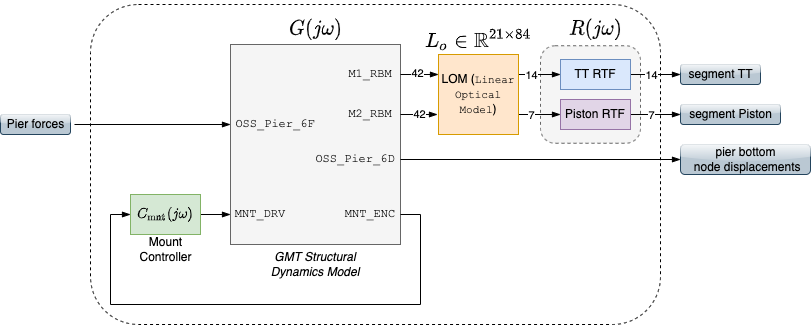

nw = 2^11+1;
freq = linspace(0, 500, nw);
om = freq*2*pi;

**Structural plant frequency response model**

G_fr = frd(bode_second_order(obj_sys, om, om0, proportionalDampingVec, 1:nu, 1:ny), om, mount.Ts);
% fprintf("Done!")

**MNT Controller + drives FR models**

% Azimuth
az_dtHfb = ss(mount.az.SSdtHfb.A,...
            mount.az.SSdtHfb.B,...
            mount.az.SSdtHfb.C,...
            mount.az.SSdtHfb.D,mount.az.SSdtHfb.Ts);
az_C_fr = frd(az_dtHfb, om);
az_delay_fr = frd(tf(1,1,mount.Ts,'IOdelay',mount.az.delay/mount.Ts), om);
az_drive_fr = frd(mount.az.hDrive, om);

% Elevation
el_dtHfb = ss(mount.el.SSdtHfb.A,...
            mount.el.SSdtHfb.B,...
            mount.el.SSdtHfb.C,...
            mount.el.SSdtHfb.D,mount.el.SSdtHfb.Ts);
el_C_fr = frd(el_dtHfb, om);
el_delay_fr = frd(tf(1,1,mount.Ts,'IOdelay',mount.el.delay/mount.Ts), om);
el_drive_fr = frd(mount.el.hDrive, om);

% GIR
gir_dtHfb = ss(mount.gir.SSdtHfb.A,...
            mount.gir.SSdtHfb.B,...
            mount.gir.SSdtHfb.C,...
            mount.gir.SSdtHfb.D,mount.gir.SSdtHfb.Ts);
gir_C_fr = frd(gir_dtHfb, om);
gir_delay_fr = frd(tf(1,1,mount.Ts,'IOdelay',mount.gir.delay/mount.Ts), om);
gir_drive_fr = frd(mount.gir.hDrive, om);

**Compute telescope FRF matrix considering the mount feedback control**

if(exist("C_fresp","var")), clear C_fresp; end
C_fresp(1:6,1:6) = eye(6)*frd(tf(1,1),om);
C_fresp(6+1,6+1) = az_drive_fr * az_delay_fr * az_C_fr;
C_fresp(6+2,6+2) = el_drive_fr * el_delay_fr * el_C_fr;
C_fresp(6+3,6+3) = gir_drive_fr * gir_delay_fr * gir_C_fr;

H_mntFB = feedback(G_fr*C_fresp, eye(3),...
    obj_sys.inputs(end).indexes, obj_sys.outputs(end).indexes);

**Transfer function representing the effect of pier forces on the bottom pier displacements**

if(true)
    G_pier = frd(...
        bode_second_order(obj_pier_mnt, om, om0, proportionalDampingVec, 1:nu, 1:ny_),...
        om, mount.Ts); 
    H_pier_mntFB = feedback(G_pier*C_fresp, eye(3),...
    obj_pier_mnt.inputs(end).indexes, obj_pier_mnt.outputs(end).indexes);
    
    show_pier_TF = true;
else, show_pier_TF = false;
end

**Compute NS or LTAO RTFs for a particular frequency **

The variable `rtf` is a $21\times21$matrix transfer function. The NS or LTAO (depending on the argument state of `NS_MODE`) tip-tilt rejection transfer function (RTF) fills the first 14 main diagonal entries. The differential piston RTF fills the last 7 diagonal elements if the checkbox is unchecked, meaning that one assumes the LTAO observing mode. Otherwise, those diagonals are filled with 1s. The rejection transfer function matrix aims at reproducing the effect of the wavefront control loops.

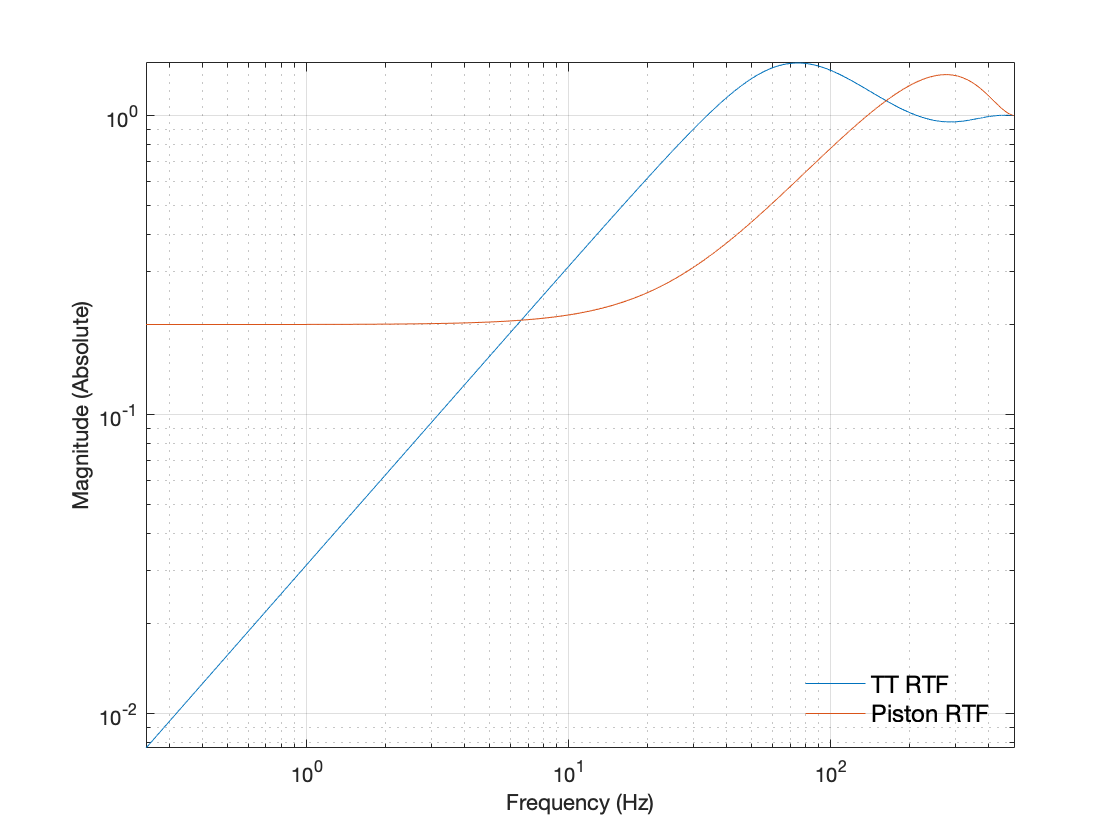

if(exist("rtf","var")), clear rtf; end
if(~true)
    rtf(1:14,1:14) = eye(14)*frd(oad_NS_rtf(om), om);  
    rtf(15:21,15:21) = eye(7)*frd(tf(1,1), om);
else    
    rtf(1:14,1:14) = eye(14)*frd(oad_AOTT_rtf(om), om);
    rtf(15:21,15:21) = eye(7)*frd(getRTF_DP(om), om);
end
rtf = frd(rtf.ResponseData, om, mount.Ts);

if(true)
    figure;
    loglog(om/2/pi,abs(squeeze(rtf.ResponseData(1,1,:)))); hold on;
    loglog(om/2/pi,abs(squeeze(rtf.ResponseData(15,15,:))));
    legend('TT RTF','Piston RTF','Fontsize',12,'Location','southeast');
    legend box off;
    xlabel('Frequency (Hz)'); ylabel('Magnitude (Absolute)');
    grid on; hold off; axis tight;
end

Apply rejection transfer functions

H_pier = rtf * H_mntFB(1:21,1:6,:);

## Evaluate vibration TF frequency responses

plotOutLabel = {'F_x','F_y','F_z','M_x','M_y','M_z'};
plotUnitstr = {'N','N','N','Nm','Nm','Nm'};
reposFIGs = [1,3,5,2,4,6];


### Pier forces to displacements

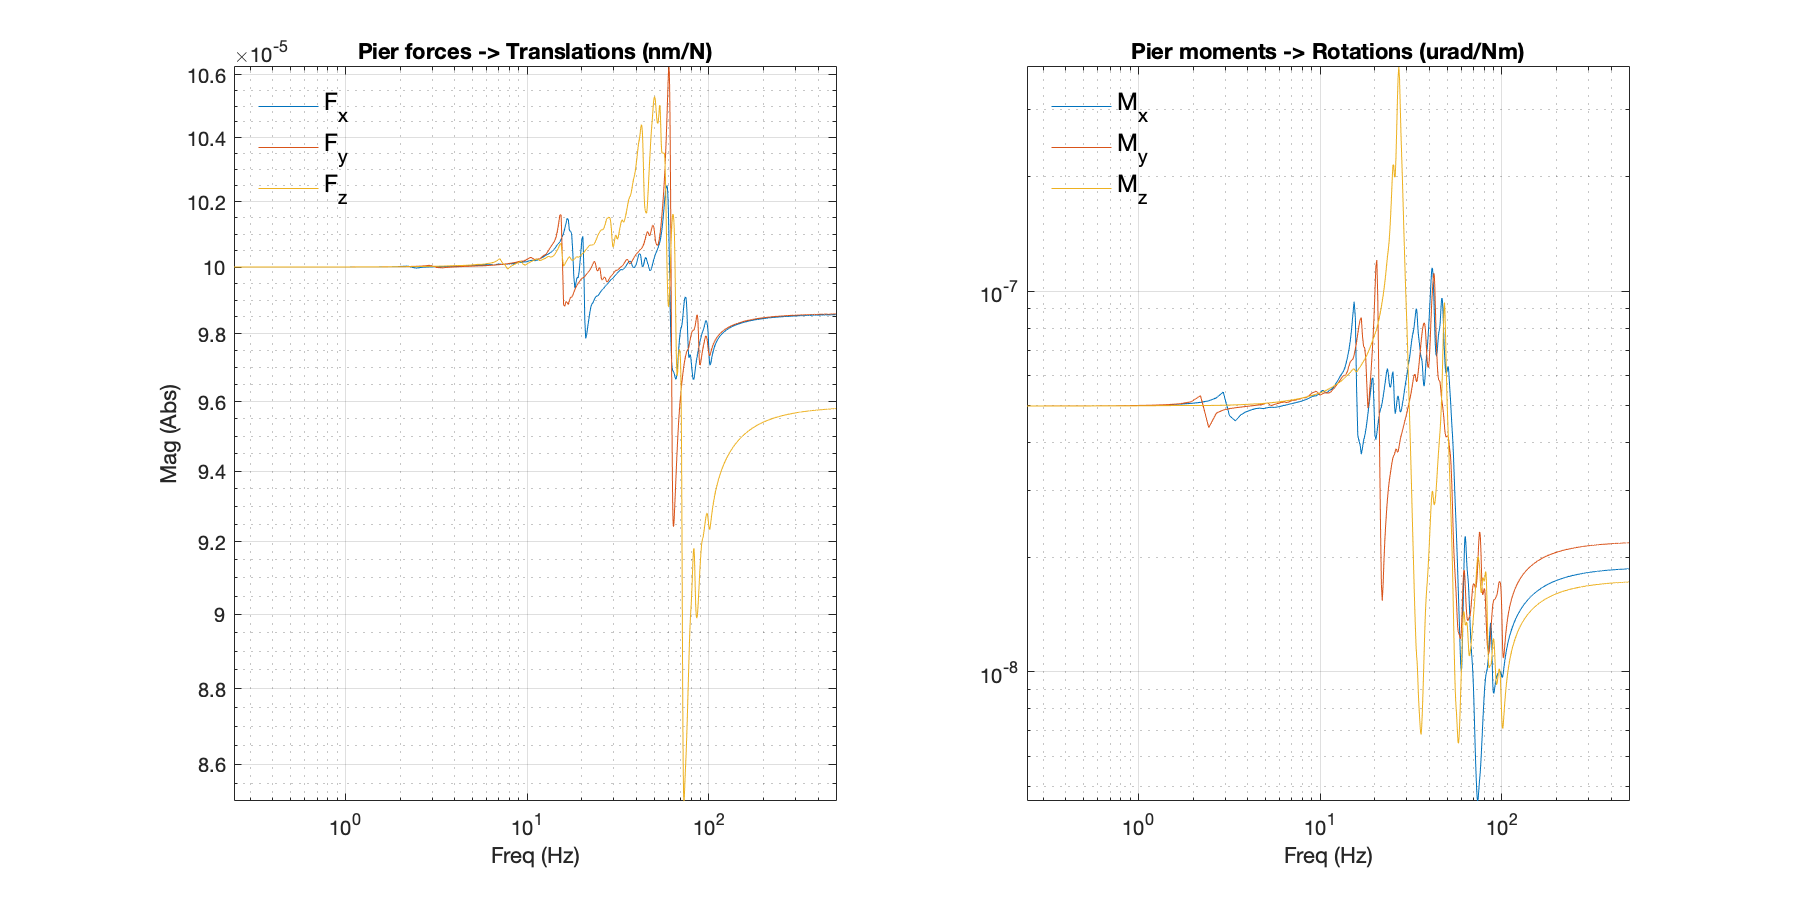

if(show_pier_TF)
    figure;
    set(gcf,'Position',[833   323   900   450])
    set(gcf,'Name','FRF mag - Pier Forces to Displacements');
    
    subplot(121);
    for i2 = 1:3
        loglog(om/2/pi, 1e9*abs(squeeze(H_pier_mntFB.ResponseData(i2,i2,:))));
        hold on;
    end
    legend(plotOutLabel{1:3},'Fontsize',12,'location','northwest'); legend boxoff;
    axis tight; ylabel('Mag (Abs)'); xlabel('Freq (Hz)'); grid on; hold off;
    title('Pier forces -> Translations (nm/N)');
    
    subplot(122);
    for i2 = 4:6
        loglog(om/2/pi, 1e6*abs(squeeze(H_pier_mntFB.ResponseData(i2,i2,:))));
        hold on;
    end
    legend(plotOutLabel{4:6},'Fontsize',12,'location','northwest'); legend boxoff;
    axis tight; xlabel('Freq (Hz)'); grid on; hold off;
    title('Pier moments -> Rotations (urad/Nm)');
    
end

### Segment TT

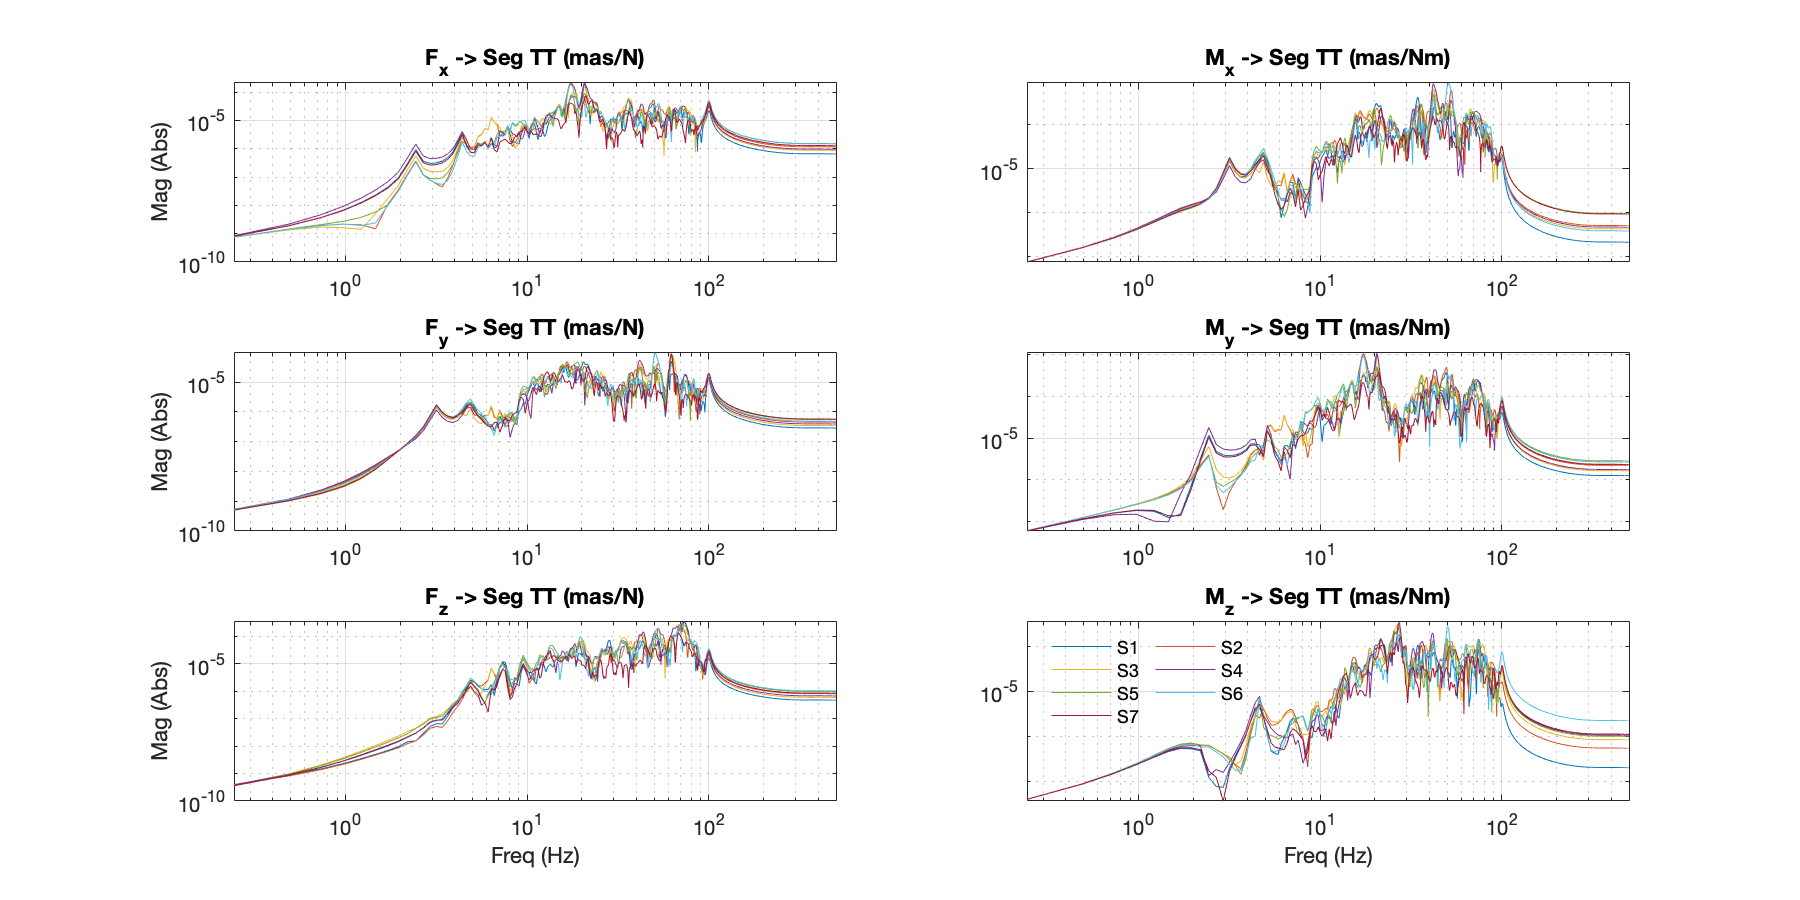

figure;
set(gcf,'Position',[833   323   900   450])
set(gcf,'Name','FRF mag - Pier 6F to Seg Tip');
tt_frf = zeros(7,6,length(om));
for i2 = 1:6
    subplot(3,2,reposFIGs(i2));
    tt_frf(:,i2,:) = rad2mas * abs(sqrt(...
        H_pier.ResponseData(1:7,i2,:).^2 + ...
        H_pier.ResponseData((1:7)+7,i2,:).^2));
    loglog(om/2/pi, squeeze(tt_frf(:,i2,:)));
    xlim([min(om/2/pi),max(om/2/pi)]);
    
    title(sprintf('%s -> Seg TT (mas/%s)',plotOutLabel{i2},plotUnitstr{i2}));
    if(reposFIGs(i2) >= 5), xlabel('Freq (Hz)'); end
    if(mod(reposFIGs(i2),2)), ylabel('Mag (Abs)'); end
    grid on;
end
legend('S1','S2','S3','S4','S5','S6','S7',...
        'NumColumns',2,'Orientation',"horizontal",...
        'Location','northwest');
legend boxoff;

### Segment Piston

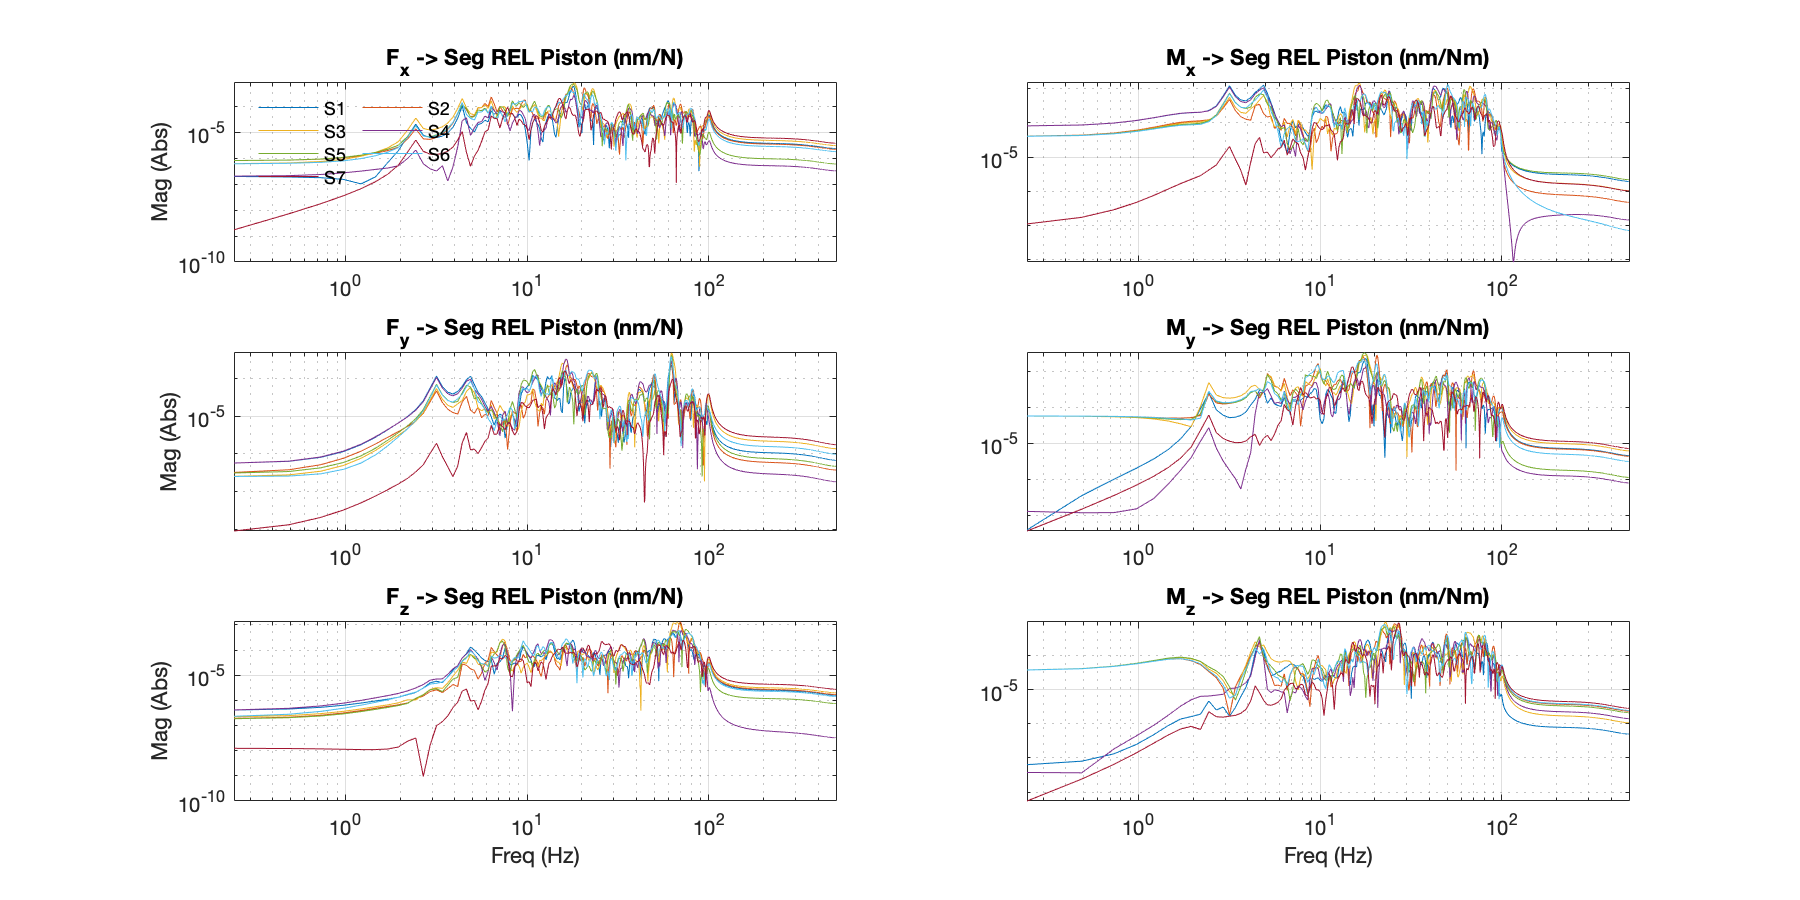

figure;
set(gcf,'Position',[833   323   900   450])
set(gcf,'Name','FRF mag - Pier 6F to Seg Piston');
piston_frf = zeros(size(tt_frf));
rel_piston_frf = zeros(size(piston_frf));
for i2 = 1:6    
    subplot(3,2,reposFIGs(i2));
    piston_frf(:,i2,:) = 1e9*abs(H_pier.ResponseData(15:21,i2,:));
    rel_piston_frf(:,i2,:) = 1e9*abs(H_pier.ResponseData(15:21,i2,:) -...
        mean(H_pier.ResponseData(15:21,i2,:)));
    loglog(om/2/pi, squeeze(rel_piston_frf(:,i2,:)));
    xlim([min(om/2/pi),max(om/2/pi)]);
    
    title(sprintf('%s -> Seg REL Piston (nm/%s)',plotOutLabel{i2},plotUnitstr{i2}));
    if(reposFIGs(i2) >= 5), xlabel('Freq (Hz)'); end
    if(mod(reposFIGs(i2),2)), ylabel('Mag (Abs)'); end
    grid on;
end
subplot(321)
legend('S1','S2','S3','S4','S5','S6','S7',...
        'NumColumns',2,'Orientation',"horizontal",...
        'Location','northwest');
legend boxoff;

### White-noise wavefront error (WFE) responses

Let $Y_\text{tt}(j\omega) = H_\text{tt}(j\omega) U_\text{pier}(j\omega)$ the 14-dimensional vector of segment tip-tilt. Similarly, $Y_\text{piston}(j\omega) = H_\text{piston
}(j\omega) U_\text{pier}(j\omega)$ denotes the 7-dimensional vector segment piston response to a particular input $U_\text{pier}(j\omega)$. One can approximate the wavefront error***** induced by $U_\text{pier}(j\omega)$as

$Y_\text{wf}(j\omega) = \sqrt{
\left(\rho \breve{Y}_\text{tt}(j\omega)\right)^2 +
\left(\breve{Y}_\text{piston}(j\omega)\right)^2
}$,

with $\rho = 10.2 \frac{\text{nm}}{\text{mas}}$,


$$\breve{Y}_\text{tt}(j\omega) = 
\sqrt{
\frac{1}{7} \sum_{i=1}^7
 \left(
Y_{\text{tt},i}(j\omega) \right) ^2 
+ \left(Y_{\text{tt},i+7}(j\omega)
\right)^2 }$$


and


$$\breve{Y}_\text{piston}(j\omega) = 
\sqrt{
\frac{1}{7} \sum_{i=1}^7
\left(Y_{\text{piston},i}(j\omega) - \frac{1}{7} \sum_{i=1}^7
Y_{\text{piston},i}(j\omega)\right)^2} ,$$


where $Y_{\text{tt},i}(j\omega)$ and $Y_{\text{piston},i}(j\omega)$ denote the $i^\text{th}$-element of $Y_\text{tt}(j\omega)$and $Y_\text{piston}(j\omega)$, respectively.

In the following, we present the white-noise response $Y_\text{wf}(j\omega)$.

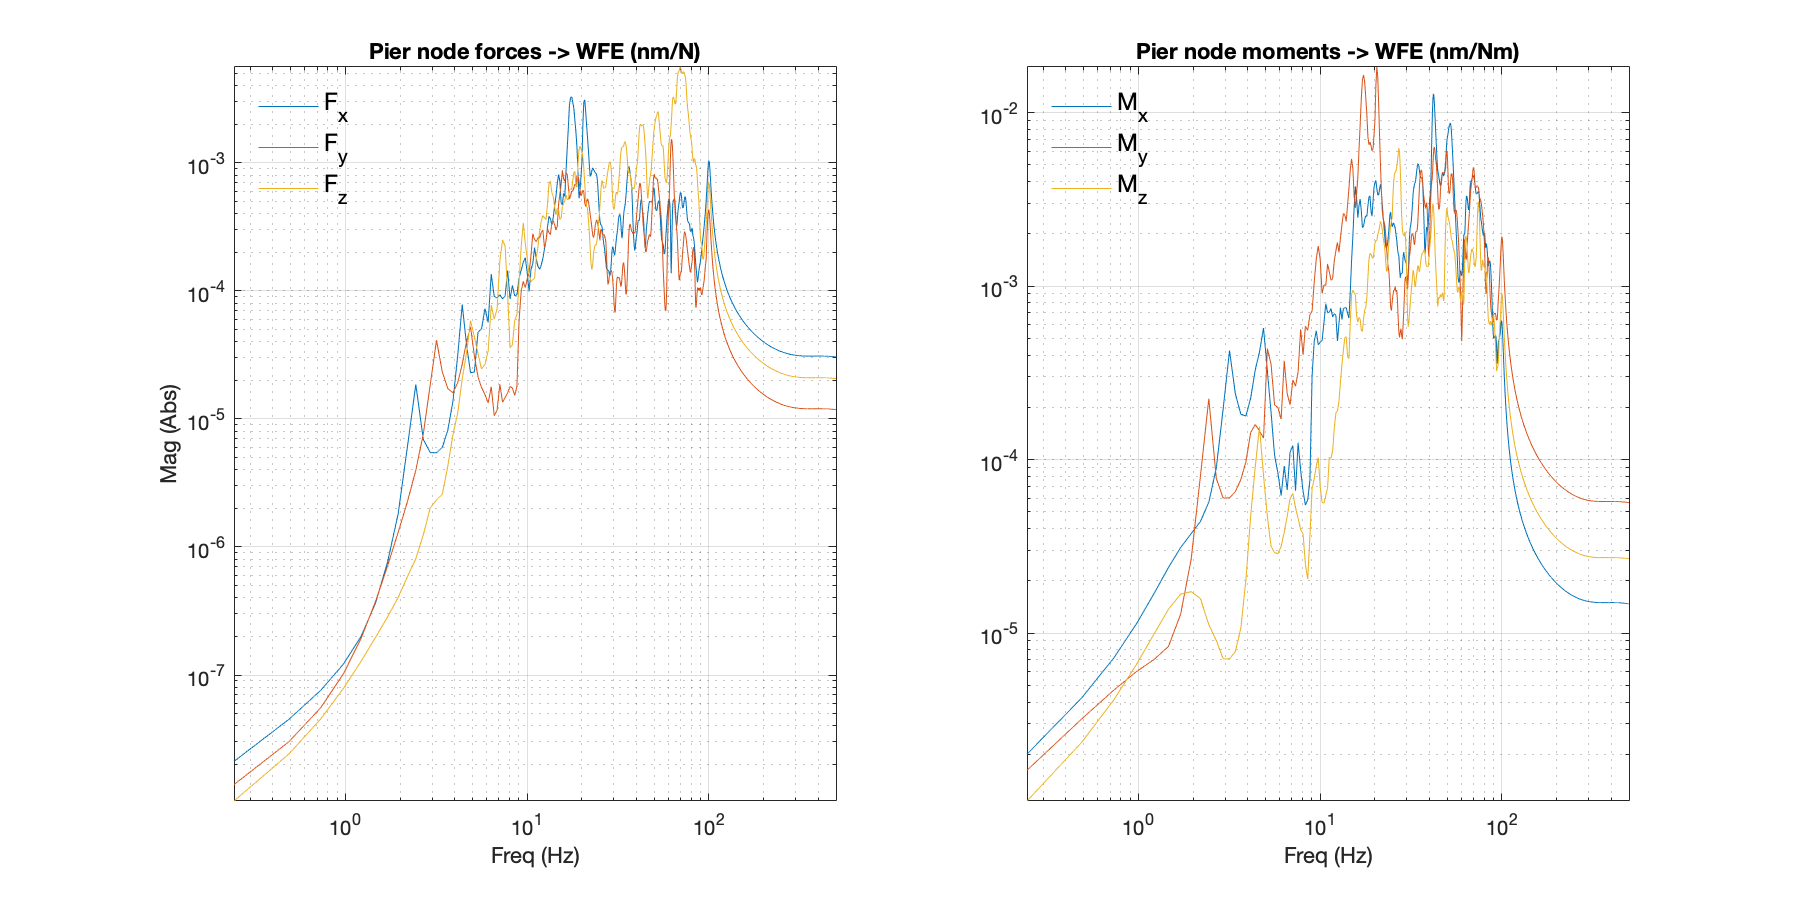

figure;
set(gcf,'Position',[833   323   900   450])
set(gcf,'Name','FRF mag - Pier 6F to Seg Piston');
wfe = zeros(6,length(om));

subplot(121);
for i2 = 1:3
    wfe(i2,:) = sqrt(1/7) * sqrt((10.2*sum(tt_frf(:,i2,:),1)).^2 +...
       sum(piston_frf(:,i2,:) - mean(piston_frf(:,i2,:),1)).^2);
    loglog(om/2/pi, squeeze(wfe(i2,:)));
    hold on;
end
legend(plotOutLabel{1:3},'Fontsize',12,'location','northwest'); legend boxoff;
axis tight; ylabel('Mag (Abs)'); xlabel('Freq (Hz)'); grid on; hold off;
title('Pier node forces -> WFE (nm/N)');




subplot(122);
for i2 = 4:6
    wfe(i2,:) = sqrt((1/7)*(10.2*sum(tt_frf(:,i2,:),1)).^2 +...
       (1/7)*sum(piston_frf(:,i2,:) - mean(piston_frf(:,i2,:),1)).^2);
    loglog(om/2/pi, squeeze(wfe(i2,:)));
    hold on;
end
legend(plotOutLabel{4:6},'Fontsize',12,'location','northwest'); legend boxoff;
axis tight; xlabel('Freq (Hz)'); grid on; hold off;
title('Pier node moments -> WFE (nm/Nm)');

**Auxiliar functions providing the NS/LTAO RTFs (Rejection Transfer Functions)**

Function to compute the NS RTF (according to REQ-L3-OAD-35337)

function [rtf,L] = oad_NS_rtf(w)  

% PZT closed-loop bandwidth (Hz)
fz = 25;
% PZT control loop damping
delta = 0.6;
% TT loop sampling period
T = 5e-3;
% TT sensor delay
tau = 6e-3;
% TT "integral gain" - actually the considered integral gain is gi/T
gi = 0.3;

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the GLAO RTF (according to REQ-L3-OAD-35398)

function [rtf,L] = oad_AOTT_rtf(w)

% LTAO RTF (according to REQ-L3-OAD-35398)
fz = 800;       % ASM closed-loop bandwidth (Hz)
delta = 0.75;   % ASM control loop damping
T = 2e-3;   % TT loop sampling period
tau = 1e-3; % TT sensor delay
gi = 0.4;   % TT "integral gain"

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the differential piston RTF

function RTF_DP = getRTF_DP(om)
    
s = sqrt(-1)*om;

%% FROM DRD rev F
omz = 800*2*pi;
dz = .75;
Tp = 30;
taup= 6/1000;
gpi = .5;
Te = 2/1000;
taue = .1/1000;
geff = .8;

num = 1 + omz^2*geff*exp(-taue*s).*(exp(-Te*s)-1)./(Te*s.*    (omz^2+2*omz*dz*s+s.^2) );
den = 1 - omz^2*gpi*exp(-taup*s).*(exp(-Tp*s)-1)./(Tp^2*s.^2.*(omz^2+2*omz*dz*s+s.^2) );
RTF_DP = num./den;
    
end